solinit = bvpinit(linspace(0,1),[2;3;1;1;2]);
sol = bvp4c(@ode, @bc, solinit);
y = sol.y;
time = y(5)*sol.x;
ut = -y(4,:);

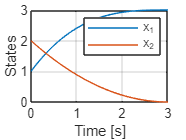

plot(time,y(1,:),"DisplayName","x_1")
hold on
plot(time,y(2,:),"DisplayName","x_2")
legend
xlabel("Time [s]")
ylabel("States")
grid on;

function dydt = ode(t,y)
% -------------------------------------------------------------------------
% ODE’s of augmented states
    dydt = y(5)*[ y(2);-y(4);0;-y(3);0 ];
end
% -------------------------------------------------------------------------
% boundary conditions: x1(0)=1;x2(0)=2, x1(tf)=3, p2(tf)=0;

% p1(tf)*x2(tf)-0.5*p2(2)^2
function res = bc(ya,yb)
    res = [ ya(1) - 1; ya(2) - 2; yb(1) - 3; yb(4);
    yb(3)*yb(2)-0.5*yb(4)^2];
end